%% Chaff Simulation with Lengths and Orientations
% This script models chaff distributions in 3D space, incorporating:
% - Variable chaff lengths
% - Orientation vectors
% - Visualisation for both Monte Carlo and Gaussian distributions

%% Parameters
% Define global parameters for all simulations
lambda = 10e-2;          % Wavelength in meters (example: 10 cm)
meanLength = lambda / 2; % Mean chaff length
stdDev = 0.01;           % Standard deviation of chaff lengths (1 cm)
minLength = 0.01;        % Minimum chaff length (1 cm)
numParticles = 1000;     % Number of chaff particles

% Orientation parameters
azimuthRange = [0, 2*pi]; % Azimuth angles (radians)
elevationRange = [0, pi]; % Elevation angles (radians)

% Gaussian position distribution parameters
mu = [0, 0, 10]; % Mean position (center at [0, 0, 10])
sigma = [5, 5, 2]; % Standard deviations in X, Y, Z directions

% Monte Carlo bounds for positions
xBounds = [-10, 10]; 
yBounds = [-10, 10];
zBounds = [0, 20];

%% Generate Chaff Lengths
% Create chaff lengths using a normal distribution and truncate at minLength
chaffLengths = meanLength + stdDev * randn(numParticles, 1);
chaffLengths(chaffLengths < minLength) = minLength;

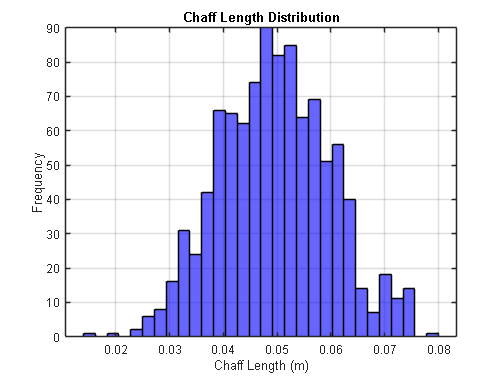

% Visualise chaff length distribution
figure;
histogram(chaffLengths, 30, 'FaceColor', 'b', 'EdgeColor', 'k');
title('Chaff Length Distribution');
xlabel('Chaff Length (m)');
ylabel('Frequency');
grid on;

%% Monte Carlo Distribution with Orientation
% Generate Monte Carlo positions
xMC = xBounds(1) + (xBounds(2) - xBounds(1)) * rand(numParticles, 1);
yMC = yBounds(1) + (yBounds(2) - yBounds(1)) * rand(numParticles, 1);
zMC = zBounds(1) + (zBounds(2) - zBounds(1)) * rand(numParticles, 1);

% Generate random orientations for Monte Carlo
azimuthMC = azimuthRange(1) + (azimuthRange(2) - azimuthRange(1)) * rand(numParticles, 1);
elevationMC = elevationRange(1) + (elevationRange(2) - elevationRange(1)) * rand(numParticles, 1);

% Convert orientations to vector components
uMC = cos(azimuthMC) .* sin(elevationMC) .* chaffLengths;
vMC = sin(azimuthMC) .* sin(elevationMC) .* chaffLengths;
wMC = cos(elevationMC) .* chaffLengths;

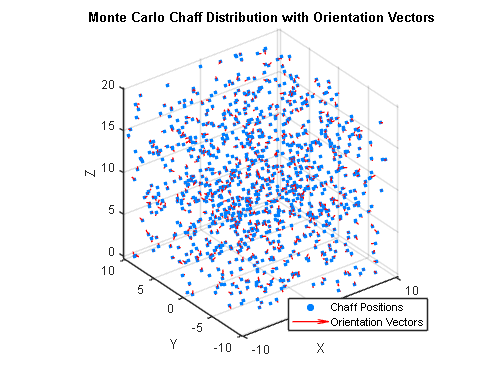

% Visualise Monte Carlo distribution with orientation
figure;
scatter3(xMC, yMC, zMC, 10, 'filled', 'MarkerFaceColor', [0, 0.5, 1]);
hold on;
quiver3(xMC, yMC, zMC, uMC, vMC, wMC, 0.5, 'Color', 'r', 'LineWidth', 1);
hold off;
title('Monte Carlo Chaff Distribution with Orientation Vectors');
xlabel('X'); ylabel('Y'); zlabel('Z');
legend({'Chaff Positions', 'Orientation Vectors'}, 'Location', 'Best');
grid on; axis equal;

%% Gaussian Distribution with Orientation
% Generate Gaussian positions
xGaussian = mu(1) + sigma(1) * randn(numParticles, 1);
yGaussian = mu(2) + sigma(2) * randn(numParticles, 1);
zGaussian = mu(3) + sigma(3) * randn(numParticles, 1);

% Generate random orientations for Gaussian
azimuthGaussian = azimuthRange(1) + (azimuthRange(2) - azimuthRange(1)) * rand(numParticles, 1);
elevationGaussian = elevationRange(1) + (elevationRange(2) - elevationRange(1)) * rand(numParticles, 1);

% Convert orientations to vector components
uGaussian = cos(azimuthGaussian) .* sin(elevationGaussian) .* chaffLengths;
vGaussian = sin(azimuthGaussian) .* sin(elevationGaussian) .* chaffLengths;
wGaussian = cos(elevationGaussian) .* chaffLengths;

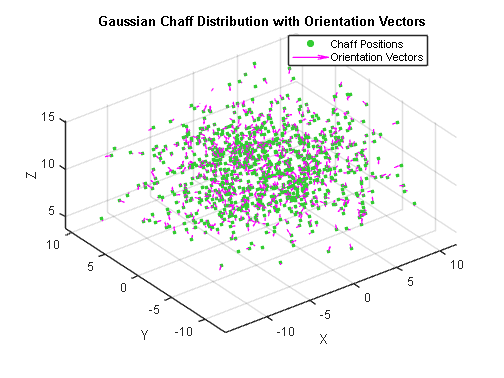

% Visualise Gaussian distribution with orientation
figure;
scatter3(xGaussian, yGaussian, zGaussian, 10, 'filled', 'MarkerFaceColor', [0.2, 0.8, 0.2]);
hold on;
quiver3(xGaussian, yGaussian, zGaussian, uGaussian, vGaussian, wGaussian, 0.5, 'Color', 'm', 'LineWidth', 1);
hold off;
title('Gaussian Chaff Distribution with Orientation Vectors');
xlabel('X'); ylabel('Y'); zlabel('Z');
legend({'Chaff Positions', 'Orientation Vectors'}, 'Location', 'Best');
grid on; axis equal;

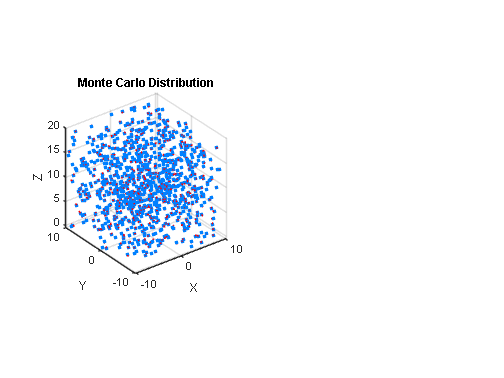

%% Comparison of Distributions
% Visualise Monte Carlo and Gaussian distributions side by side
figure;
subplot(1, 2, 1);
scatter3(xMC, yMC, zMC, 10, 'filled', 'MarkerFaceColor', [0, 0.5, 1]);
hold on;
quiver3(xMC, yMC, zMC, uMC, vMC, wMC, 0.5, 'Color', 'r');
title('Monte Carlo Distribution');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;

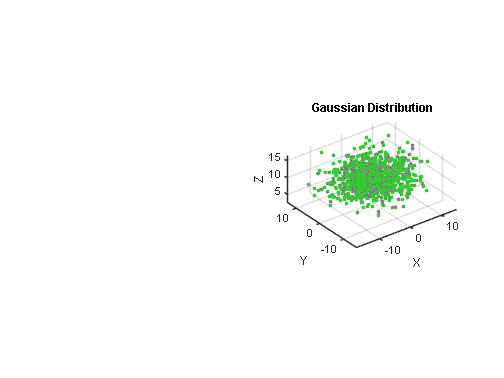

subplot(1, 2, 2);
scatter3(xGaussian, yGaussian, zGaussian, 10, 'filled', 'MarkerFaceColor', [0.2, 0.8, 0.2]);
hold on;
quiver3(xGaussian, yGaussian, zGaussian, uGaussian, vGaussian, wGaussian, 0.5, 'Color', 'm');
title('Gaussian Distribution');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;